clear;clc;

% load experimental data
data_mono = xlsread('data_to_fit.xlsx', 3, 'B9:E13');
% data_neu = xlsread('data_to_fit.xlsx', 3, 'B15:E17');
% data_nk = xlsread('data_to_fit.xlsx', 3, 'B17:E19');
data_v = xlsread('data_to_fit.xlsx', 3, 'B27:I31');
% data_t = xlsread('data_to_fit.xlsx', 3, 'B25:G27');
% data_te = xlsread('data_to_fit.xlsx', 3, 'B29:G31');
% data_il1b = xlsread('data_to_fit.xlsx', 3, 'B33:E35');
% data_ccl2 = xlsread('data_to_fit.xlsx', 3, 'B37:E39');

data_inf_score = xlsread('data_to_fit.xlsx', 3, 'B49:C53');
    
% data_v(2:3, :) = 10 .^ data_v(2:3, :);

% load immunity and clock-immunity parameters
par_IAV = importdata('par_base_IAV_clock_values.txt');
par_IAV = par_IAV.data;

% load clock parameters
par_clock = load('par_clock.csv');

% load inflammation parameters
par_infla = importdata('par_infla.txt');
par_infla = par_infla.data;

y0 = zeros(25, 1);
y0_IAV = importdata('init_base.txt');
y0_IAV = y0_IAV.data;
for i = 13:25
    y0(i) = y0_IAV(i - 12);
end

tmax = 2000;
tspan = 0:1:tmax;

t_IAV_5 = 505;
[~, y1] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_5);
infla1 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla1(i) = inflammation(y1(i, 17), y1(i, 18), par_infla);
end

% Smaller amplitude
vmax_bmal = par_clock(17);
par_clock(17) = 0.2;
[~, y1_sa] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_5);
infla1_sa = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla1_sa(i) = inflammation(y1_sa(i, 17), y1_sa(i, 18), par_infla);
end
par_clock(17) = vmax_bmal;

% par_IAV(64) = 0.02;
% par_IAV(65) = 10000;
t_IAV_11 = 511;
[~, y2] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_11);
infla2 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla2(i) = inflammation(y2(i, 17), y2(i, 18), par_infla);
end

% clock ko
[~, y2_ko] = ode15s(@ODE_Clock_KO_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_11);
infla2_ko = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla2_ko(i) = inflammation(y2_ko(i, 17), y2_ko(i, 18), par_infla);
end

% Smaller amplitude
vmax_bmal = par_clock(17);
par_clock(17) = 0.2;
[~, y2_sa] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_11);
infla2_sa = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla2_sa(i) = inflammation(y2_sa(i, 17), y2_sa(i, 18), par_infla);
end
par_clock(17) = vmax_bmal;

t_IAV_17 = 517;
[~, y3] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_17);
infla3 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla3(i) = inflammation(y3(i, 17), y3(i, 18), par_infla);
end

% Smaller amplitude
vmax_bmal = par_clock(17);
par_clock(17) = 0.2;
[~, y3_sa] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_17);
infla3_sa = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla3_sa(i) = inflammation(y3_sa(i, 17), y3_sa(i, 18), par_infla);
end
par_clock(17) = vmax_bmal;

% par_IAV(70) = 0.02;
% par_IAV(71) = 10000;
% t_IAV_5 = 505;
% [~, y2] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_5, par_infla);
% infla2 = zeros(tmax+1, 1);
% for i = 1:(tmax+1)
%     infla2(i) = inflammation(y2(i, 17), y2(i, 18), y2(i, 19), par_infla);
% end

% par_IAV(70) = 10000;
% par_IAV(71) = 0.02;
% par_clock(8) = 0.6;
t_IAV_23 = 523;
[~, y4] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_23);
infla4 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla4(i) = inflammation(y4(i, 17), y4(i, 18), par_infla);
end

% clock ko
[~, y4_ko] = ode15s(@ODE_Clock_KO_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_23);
infla4_ko = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla4_ko(i) = inflammation(y4_ko(i, 17), y4_ko(i, 18), par_infla);
end

% Smaller amplitude
vmax_bmal = par_clock(17);
par_clock(17) = 0.2;
[~, y4_sa] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_23);
infla4_sa = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla4_sa(i) = inflammation(y4_sa(i, 17), y4_sa(i, 18), par_infla);
end
par_clock(17) = vmax_bmal;

% turn over phase of mono and neu before infection
[~, y1_phase] = ode15s(@ODE_Clock_IAV_phase, tspan, y0, [], par_clock, par_IAV, t_IAV_5);
infla1_phase = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla1_phase(i) = inflammation(y1_phase(i, 17), y1_phase(i, 18), par_infla);
end

[~, y2_phase] = ode15s(@ODE_Clock_IAV_phase, tspan, y0, [], par_clock, par_IAV, t_IAV_11);
infla2_phase = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla2_phase(i) = inflammation(y2_phase(i, 17), y2_phase(i, 18), par_infla);
end

[~, y3_phase] = ode15s(@ODE_Clock_IAV_phase, tspan, y0, [], par_clock, par_IAV, t_IAV_17);
infla3_phase = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla3_phase(i) = inflammation(y3_phase(i, 17), y3_phase(i, 18), par_infla);
end

[~, y4_phase] = ode15s(@ODE_Clock_IAV_phase, tspan, y0, [], par_clock, par_IAV, t_IAV_23);
infla4_phase = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla4_phase(i) = inflammation(y4_phase(i, 17), y4_phase(i, 18), par_infla);
end


% change k_1 t0 generate new peak time
k1 = par_IAV(3);
par_IAV(3) = 0.2;

[~, y1_k1] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_5);
infla1_k1 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla1_k1(i) = inflammation(y1_k1(i, 17), y1_k1(i, 18), par_infla);
end

[~, y2_k1] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_11);
infla2_k1 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla2_k1(i) = inflammation(y2_k1(i, 17), y2_k1(i, 18), par_infla);
end

[~, y3_k1] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_17);
infla3_k1 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla3_k1(i) = inflammation(y3_k1(i, 17), y3_k1(i, 18), par_infla);
end

[~, y4_k1] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_23);
infla4_k1 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla4_k1(i) = inflammation(y4_k1(i, 17), y4_k1(i, 18), par_infla);
end

par_IAV(3) = k1;

% run k_I - tau relationship

n_kI = 100;
par_IAV_kI = zeros(length(par_IAV), n_kI);
for i = 1:n_kI
    par_IAV_kI(:, i) = par_IAV;
    par_IAV_kI(3, i) = i * 0.1;
end

y11s = zeros(tmax+1, 25, n_kI);
y23s = zeros(tmax+1, 25, n_kI);

t_IAV_11 = 511;
parfor i = 1:n_kI
    [~, y11s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV_kI(:, i), t_IAV_11);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 12).


y11s = real(y11s);

t_IAV_23 = 523;
parfor i = 1:n_kI
    [~, y23s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV_kI(:, i), t_IAV_23);
end
y23s = real(y23s);

tau_11s_kI = zeros(n_kI, 1);
tau_23s_kI = zeros(n_kI, 1);

for i = 1:n_kI
    [~, tau_11s_kI(i)] = max(y11s(:, 15, i));
    [~, tau_23s_kI(i)] = max(y23s(:, 15, i));
end

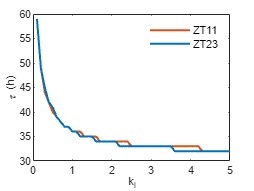

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(par_IAV_kI(3, :), tau_11s_kI - t_IAV_11, 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(par_IAV_kI(3, :), tau_23s_kI - t_IAV_23, 'Color', color4(4, :), 'LineWidth', 1.5); hold on;

xlim([0 5]);
xlabel('k_I','Fontsize',8, 'FontName', 'Arial'); ylabel('\tau (h)','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;


% change gamma t0 generate new peak time
gamma = par_IAV(4);
par_IAV(4) = 1200;

[~, y1_gamma] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_5);
infla1_gamma = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla1_gamma(i) = inflammation(y1_gamma(i, 17), y1_gamma(i, 18), par_infla);
end

[~, y2_gamma] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_11);
infla2_gamma = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla2_gamma(i) = inflammation(y2_gamma(i, 17), y2_gamma(i, 18), par_infla);
end

[~, y3_gamma] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_17);
infla3_gamma = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla3_gamma(i) = inflammation(y3_gamma(i, 17), y3_gamma(i, 18), par_infla);
end

[~, y4_gamma] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_23);
infla4_gamma = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla4_gamma(i) = inflammation(y4_gamma(i, 17), y4_gamma(i, 18), par_infla);
end

par_IAV(4) = gamma;

% run gamma - tau relationship

n_kI = 100;
par_IAV_gamma = zeros(length(par_IAV), n_kI);
for i = 1:n_kI
    par_IAV_gamma(:, i) = par_IAV;
    par_IAV_gamma(4, i) = i * 20;
end

y11s = zeros(tmax+1, 25, n_kI);
y23s = zeros(tmax+1, 25, n_kI);

t_IAV_11 = 511;
parfor i = 1:n_kI
    [~, y11s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV_gamma(:, i), t_IAV_11);
end
y11s = real(y11s);

t_IAV_23 = 523;
parfor i = 1:n_kI
    [~, y23s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV_gamma(:, i), t_IAV_23);
end
y23s = real(y23s);

tau_11s_gamma = zeros(n_kI, 1);
tau_23s_gamma = zeros(n_kI, 1);

for i = 1:n_kI
    [~, tau_11s_gamma(i)] = max(y11s(:, 15, i));
    [~, tau_23s_gamma(i)] = max(y23s(:, 15, i));
end

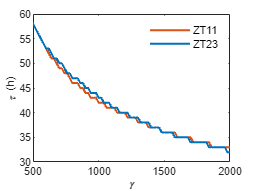

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(par_IAV_gamma(4, :), tau_11s_gamma - t_IAV_11, 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(par_IAV_gamma(4, :), tau_23s_gamma - t_IAV_23, 'Color', color4(4, :), 'LineWidth', 1.5); hold on;

xlim([500 2000]);
xlabel('\gamma','Fontsize',8, 'FontName', 'Arial'); ylabel('\tau (h)','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

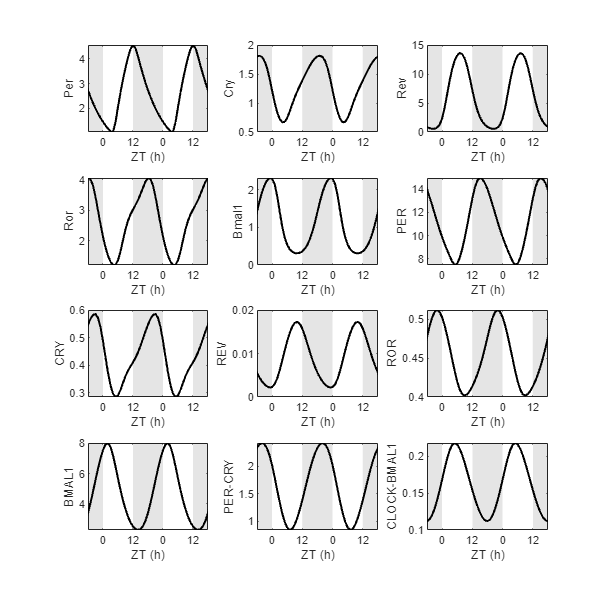

% dark regions
ymin = 0; ymax = 100;
v2 = [446 ymin; 452 ymin; 452 ymax; 446 ymax;
    464 ymin; 476 ymin; 476 ymax; 464 ymax;
    488 ymin; 494 ymin; 494 ymax; 488 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12];

clock_name = ["Per", "Cry", "Rev", "Ror", "Bmal1", "PER", "CRY", "REV", "ROR", "BMAL1", "PER-CRY", "CLOCK-BMAL1"];
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gcf, 'unit', 'centimeters', 'position', [10 5 16 16]);
for i = 1:12
    subplot(4, 3, i);
%     plot(tspan, y2(:, i), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
    plot(tspan, y2(:, i), 'k', 'LineWidth', 1.5); hold on;
%     plot(tspan, y4(:, i), 'Color', color4(4, :), 'LineWidth', 1.5); hold on;
%     plot(tspan, y4(:, i), 'b', 'LineWidth', 1); hold on;
%     xlim([490 550]);
    xlim([446 494]);
    xticks([452 464 476 488]);
    xticklabels({'0', '12', '0', '12'});
    yl = ylim;
    patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
    ylim(yl);
    xlabel('ZT (h)');
    ylabel(clock_name(i));
end
% sgtitle('Time evolution of clock components');
hold off;

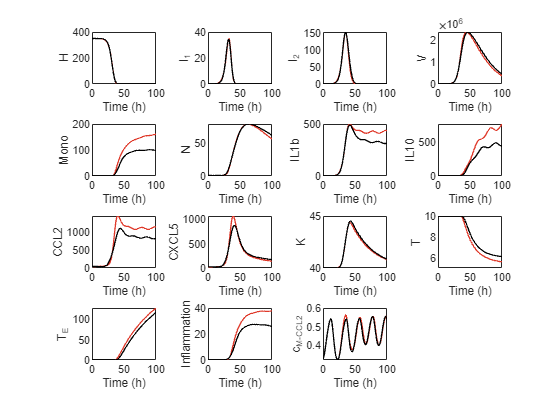


% figure;
% xSize = 30; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
% set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
% hold on;
% subplot(1, 3, 1);
% plot(par_IAV(71) ./ (par_IAV(71) + y2(:, 8)) * par_IAV(20), 'k', 'LineWidth', 2); hold on;
% plot([100 200], [0.7 0.7], 'g', 'LineStyle', '--', 'LineWidth', 2); hold off;
% xlim([100 200]); ylim([0.6 1.3]); xlabel('Time (h)'); ylabel('c_{M-CCL2}'); title('Normal Clock');
% subplot(1, 3, 2);
% plot(par_IAV(71) ./ (par_IAV(71) + y3(:, 8)) * par_IAV(20), 'r', 'LineWidth', 2); hold on;
% plot([100 200], [0.7 0.7], 'g', 'LineStyle', '--', 'LineWidth', 2); hold off;
% xlim([100 200]); ylim([0.6 1.3]); xlabel('Time (h)'); ylabel('c_{M-CCL2}'); title('Clock Knock Out');
% subplot(1, 3, 3);
% plot(par_IAV(71) ./ (par_IAV(71) + y4(:, 8)) * par_IAV(20), 'b', 'LineWidth', 2); hold on;
% plot([100 200], [0.7 0.7], 'g', 'LineStyle', '--', 'LineWidth', 2); hold off;
% xlim([100 200]); ylim([0.6 1.3]); xlabel('Time (h)'); ylabel('c_{M-CCL2}'); title('Smaller Amplitude');

var_name = ["H", "I_1", "I_2", "V", "Mono", "N", "IL1b", "IL10", "CCL2", "CXCL5", "K", "T", "T_E"];
figure;
for i = 13:25
    subplot(4, 4, i - 12);
%     plot(tspan, y(:, i), 'k', 'LineWidth', 1); hold on;
%     plot(tspan, y1(:, i), 'r', 'LineWidth', 1);
%     plot(tspan - t_IAV_5, y1(:, i), 'Color', '#0072BD', 'LineWidth', 1); hold on;
    plot(tspan - t_IAV_11, y2(:, i), 'Color', '#DF392A', 'LineWidth', 1); hold on;
%     plot(tspan - t_IAV_5, y2(:, i), 'k', 'LineWidth', 1); hold on;
%     plot(tspan - t_IAV_17, y3(:, i), 'Color', '#7E2F8E', 'LineWidth', 1); hold on;
    plot(tspan - t_IAV_23, y4(:, i), 'Color', '#000000', 'LineWidth', 1); hold on;
%     plot(tspan - t_IAV_23, y4(:, i), 'b', 'LineWidth', 1);
%     xlim([0 500]);
    xlim([0 100]);
%     xlim([446 494]);
%     yl = ylim;
%     patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
%     ylim(yl);
    xlabel('Time (h)');
    ylabel(var_name(i - 12)); hold off;
end
subplot(4, 4, 14);
% plot(tspan - t_IAV_5, infla1, 'Color', '#0072BD', 'LineWidth', 1); hold on;
plot(tspan - t_IAV_11, infla2, 'Color', '#DF392A', 'LineWidth', 1); hold on;
% plot(tspan - t_IAV_17, infla3, 'Color', '#7E2F8E', 'LineWidth', 1); hold on;
plot(tspan - t_IAV_23, infla4, 'Color', '#000000', 'LineWidth', 1); hold on;
% plot(tspan - t_IAV_23, infla4, 'b', 'LineWidth', 1);
% xlim([0 500]);
xlim([0 100]);
xlabel('Time (h)'); ylabel('Inflammation'); hold off;

subplot(4, 4, 15);
plot(tspan - t_IAV_11, par_IAV(17) .* par_IAV(55) ./ (par_IAV(55) + y2(:, 8)), 'Color', '#DF392A', 'LineWidth', 1); hold on;
plot(tspan - t_IAV_11, par_IAV(17) .* par_IAV(55) ./ (par_IAV(55) + y4(:, 8)), 'Color', '#000000', 'LineWidth', 1); 
xlim([0 100]);
xlabel('Time (h)'); ylabel('c_{M-CCL2}'); hold off;

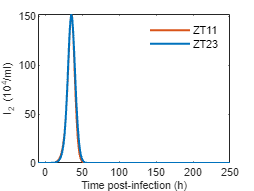

% other variables of immunity
% I2
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_11, y2(:, 15), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, y4(:, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([-10 250]);
xticks(0:50:250);
% yticks(0:25:100);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('I_2 (10^4/ml)','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'northeast');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

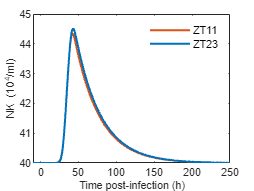


% NK
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_11, y2(:, 23), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, y4(:, 23), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([-10 250]);
xticks(0:50:250);
% yticks(0:25:100);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('NK (10^4/ml)','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'northeast');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

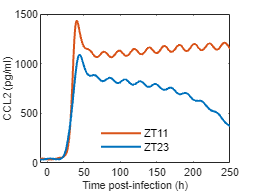


% CCL2
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_11, y2(:, 21), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, y4(:, 21), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([-10 250]);
xticks(0:50:250);
% yticks(0:25:100);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('CCL2 (pg/ml)','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'south');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

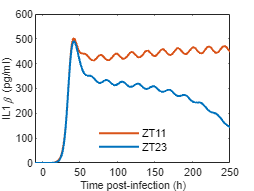


% IL1b
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_11, y2(:, 19), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, y4(:, 19), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([-10 250]);
xticks(0:50:250);
% yticks(0:25:100);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('IL1\beta (pg/ml)','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'south');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

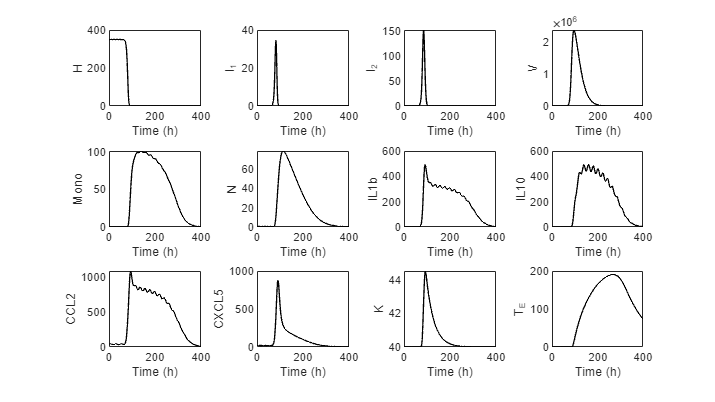

% plot variables of the model
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
figure; hold on; set(gca,'Fontsize',24, 'FontName', 'Arial'); box on;
set(gcf, 'unit', 'centimeters', 'position', [10 5 32 18]);
var_name = ["H", "I_1", "I_2", "V", "Mono", "N", "IL1b", "IL10", "CCL2", "CXCL5", "K", "T", "T_E"];
for i = 13:23
    subplot(3, 4, i - 12);
    plot(tspan - t_IAV_23 + 50, y4(:, i), 'Color', '#000000', 'LineWidth', 1); hold on;
    xlim([0 400]);
    xlabel('Time (h)');
    ylabel(var_name(i - 12)); hold off;
end
subplot(3, 4, 12);
plot(tspan - t_IAV_23 + 50, y4(:, 25), 'Color', '#000000', 'LineWidth', 1); hold on;
xlim([0 400]);
xlabel('Time (h)');
ylabel(var_name(25 - 12)); hold off;

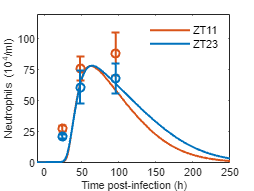

data_neu = xlsread('data_to_fit.xlsx', 3, 'B15:E17');
data_neu_sem = xlsread('data_to_fit.xlsx', 3, 'G15:J17');

figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% plot(tspan - t_IAV_5, y1(:, 17), 'LineWidth', 1.5); hold on;
% plot(tspan - t_IAV_11, y2(:, 17), 'LineWidth', 1.5); hold on;
% plot(tspan - t_IAV_17, y3(:, 17), 'LineWidth', 1.5); hold on;
% plot(tspan - t_IAV_23, y4(:, 17), 'LineWidth', 1.5);
plot(tspan - t_IAV_11, y2(:, 18), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, y4(:, 18), 'Color', color4(4, :), 'LineWidth', 1.5);
errorbar(data_neu(1, 1:3), data_neu(3, 1:3), data_neu_sem(3, 1:3), 'o', 'Color', color4(2, :), 'LineWidth', 1.5);
errorbar(data_neu(1, 1:3), data_neu(2, 1:3), data_neu_sem(2, 1:3), 'o', 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([-10 250]);
xticks(0:50:250);
yticks(0:25:100);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Neutrophils (10^4/ml)','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'northeast');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

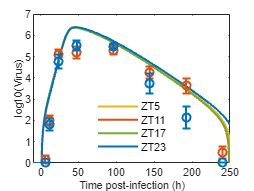

% Plot Virus and Monocytes
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% color4 = [142 207 201; 250 127 111; 255 190 122; 130 176 210] ./ 255; %
% old color4
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
plot(tspan - t_IAV_5, Safe_log10(y1(:, 16) - 100), 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_11, Safe_log10(y2(:, 16) - 100), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_17, Safe_log10(y3(:, 16) - 100), 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, Safe_log10(y4(:, 16) - 100), 'Color', color4(4, :), 'LineWidth', 1.5);
% scatter(data_v(1, :), data_v(3, :), [], color4(2, :), 'filled', '^');
% scatter(data_v(1, :), data_v(2, :), [], color4(4, :), 'filled', '^');
errorbar(data_v(1, :), data_v(3, :), data_v(5, :), 'o', 'Color', color4(2, :), 'LineWidth', 1.5);
errorbar(data_v(1, :), data_v(2, :), data_v(4, :), 'o', 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([-10 250]);
ylim([0 7]);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('log10(Virus)','Fontsize',8, 'FontName', 'Arial');
legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'south');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

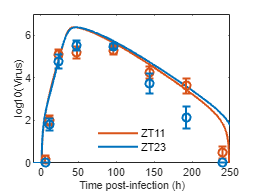


figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% color4 = [142 207 201; 250 127 111; 255 190 122; 130 176 210] ./ 255; %
% old color4
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
plot(tspan - t_IAV_11, Safe_log10(y2(:, 16) - 100), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, Safe_log10(y4(:, 16) - 100), 'Color', color4(4, :), 'LineWidth', 1.5);
errorbar(data_v(1, :), data_v(3, :), data_v(5, :), 'o', 'Color', color4(2, :), 'LineWidth', 1.5);
errorbar(data_v(1, :), data_v(2, :), data_v(4, :), 'o', 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([-10 250]);
ylim([0 7]);
yticks([0 2 4 6]);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('log10(Virus)','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'south');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

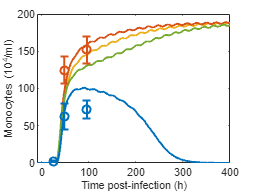


figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% plot(tspan - t_IAV_5, y1(:, 17), 'LineWidth', 1.5); hold on;
% plot(tspan - t_IAV_11, y2(:, 17), 'LineWidth', 1.5); hold on;
% plot(tspan - t_IAV_17, y3(:, 17), 'LineWidth', 1.5); hold on;
% plot(tspan - t_IAV_23, y4(:, 17), 'LineWidth', 1.5);
plot(tspan - t_IAV_5, y1(:, 17), 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_11, y2(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_17, y3(:, 17), 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, y4(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5);
% scatter(data_mono(1, 1:3), data_mono(3, 1:3), [], color4(2, :), 'filled', '^');
% scatter(data_mono(1, 1:3), data_mono(2, 1:3), [], color4(4, :), 'filled', '^');
errorbar(data_mono(1, 1:3), data_mono(3, 1:3), data_mono(5, 1:3), 'o', 'Color', color4(2, :), 'LineWidth', 1.5);
errorbar(data_mono(1, 1:3), data_mono(2, 1:3), data_mono(4, 1:3), 'o', 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([-10 400]);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)','Fontsize',8, 'FontName', 'Arial');
% legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'east');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

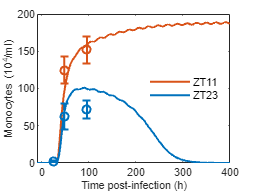


figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% plot(tspan - t_IAV_5, y1(:, 17), 'LineWidth', 1.5); hold on;
% plot(tspan - t_IAV_11, y2(:, 17), 'LineWidth', 1.5); hold on;
% plot(tspan - t_IAV_17, y3(:, 17), 'LineWidth', 1.5); hold on;
% plot(tspan - t_IAV_23, y4(:, 17), 'LineWidth', 1.5);
plot(tspan - t_IAV_11, y2(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, y4(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5);
errorbar(data_mono(1, 1:3), data_mono(3, 1:3), data_mono(5, 1:3), 'o', 'Color', color4(2, :), 'LineWidth', 1.5);
errorbar(data_mono(1, 1:3), data_mono(2, 1:3), data_mono(4, 1:3), 'o', 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([-10 400]);
xticks(0:100:400);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'east');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

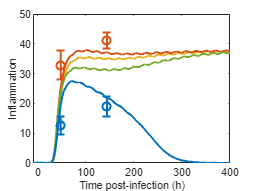

% Inflammation and survival curve
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_5, infla1, 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_11, infla2, 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_17, infla3, 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, infla4, 'Color', color4(4, :), 'LineWidth', 1.5); 
% scatter(data_inf_score(1, 1:2), data_inf_score(3, 1:2), [], color4(2, :), 'filled', '^');
% scatter(data_inf_score(1, 1:2), data_inf_score(2, 1:2), [], color4(4, :), 'filled', '^');
errorbar(data_inf_score(1, 1:2), data_inf_score(3, 1:2), data_inf_score(5, 1:2), 'o', 'Color', color4(2, :), 'LineWidth', 1.5);
errorbar(data_inf_score(1, 1:2), data_inf_score(2, 1:2), data_inf_score(4, 1:2), 'o', 'Color', color4(4, :), 'LineWidth', 1.5);

% plot(tspan - t_IAV_11, infla1_ko, 'Color', '#425CAA', 'LineWidth', 2);
% plot(tspan - t_IAV_23, infla3_ko, 'Color', '#93D8E5', 'LineWidth', 2);
% scatter(144, 36, [], [66,92,170] ./ 255, 'filled', '^');
% scatter(144, 40, [], [147,216,229] ./ 255, 'filled', '^');

xlim([-10 400]);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Inflammation','Fontsize',8, 'FontName', 'Arial');
% legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

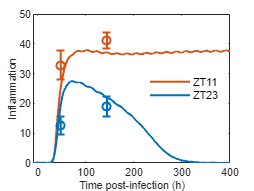


figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_11, infla2, 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, infla4, 'Color', color4(4, :), 'LineWidth', 1.5); 
errorbar(data_inf_score(1, 1:2), data_inf_score(3, 1:2), data_inf_score(5, 1:2), 'o', 'Color', color4(2, :), 'LineWidth', 1.5);
errorbar(data_inf_score(1, 1:2), data_inf_score(2, 1:2), data_inf_score(4, 1:2), 'o', 'Color', color4(4, :), 'LineWidth', 1.5);

% plot(tspan - t_IAV_11, infla1_ko, 'Color', '#425CAA', 'LineWidth', 2);
% plot(tspan - t_IAV_23, infla3_ko, 'Color', '#93D8E5', 'LineWidth', 2);
% scatter(144, 36, [], [66,92,170] ./ 255, 'filled', '^');
% scatter(144, 40, [], [147,216,229] ./ 255, 'filled', '^');

xlim([-10 400]);
xticks(0:100:400);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Inflammation','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'east');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

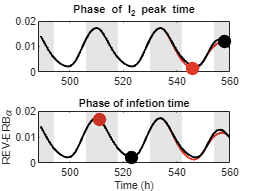

% PLot ERV-ERB phases of infection and peak time of I2
[~, peak_idx_I2_11] = max(y2(:, 15));
[~, peak_idx_I2_23] = max(y4(:, 15));

% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 560 ymin; 560 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan(490:600), y2(490:600, 8), 'Color', '#DF392A', 'LineWidth', 1.5);
plot(tspan(490:600), y4(490:600, 8), 'Color', '#000000', 'LineWidth', 1.5); 
sz = 100;
c = [[223,57,42] ./ 255; 0 0 0];
scatter([peak_idx_I2_11 - 1, peak_idx_I2_23 - 1], [y2(peak_idx_I2_11, 8), y4(peak_idx_I2_23, 8)], sz, c, 'filled');
xlim([488 560]);
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
% ylabel('REV-ERB{\alpha}');
title('Phase of I_2 peak time','Fontsize',8, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan(490:600), y2(490:600, 8), 'Color', '#DF392A', 'LineWidth', 1.5);
plot(tspan(490:600), y4(490:600, 8), 'Color', '#000000', 'LineWidth', 1.5); 
sz = 100;
c = [[223,57,42] ./ 255; 0 0 0];
scatter([t_IAV_11, t_IAV_23], [y2(t_IAV_11 + 1, 8), y4(t_IAV_23 + 1, 8)], sz, c, 'filled');
xlim([488 560]);
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('REV-ERB{\alpha}','Fontsize',8, 'FontName', 'Arial');
title('Phase of infetion time','Fontsize',8, 'FontName', 'Arial');
hold off;

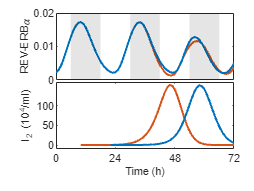

% PLot ERV-ERB phases of infection and peak time of I2
[~, peak_idx_I2_11] = max(y2(:, 15));
[~, peak_idx_I2_23] = max(y4(:, 15));

% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.22 0.58 0.7 0.35]);
plot(tspan(490:600), y2(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
sz = 100;
% c = [[223,57,42] ./ 255; 0 0 0];
% scatter([peak_idx_I2_11 - 1, peak_idx_I2_23 - 1], [y2(peak_idx_I2_11, 8), y4(peak_idx_I2_23, 8)], sz, color2, 'filled');
% scatter([t_IAV_11, t_IAV_23], [y2(t_IAV_11 + 1, 8), y4(t_IAV_23 + 1, 8)], sz, color2, '^', 'filled');
xlim([500 572]);
xticks([]);
% xticklabels({'0', '24', '48', '72'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV-ERB{\alpha}','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.22 0.22 0.7 0.35]);
plot(tspan(t_IAV_11:end), y2(t_IAV_11:end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan(t_IAV_23:end), y4(t_IAV_23:end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
yticks([0 50 100]);
yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
ylim(yl);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2 (10^4/ml)','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');
hold off;

%%%%%% figure axes parameters: inner position
% subplot 1: x:0.22, y:0.58, width:0.7, height:0.35
% subplot 2: x:0.22, y:0.22, width:0.7, height:0.35

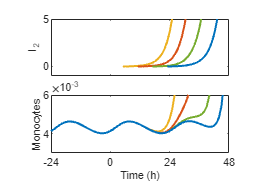

% mono and neu oscillation before infection
% PLot ERV-ERB phases of infection and peak time of I2
[~, peak_idx_I2_11] = max(y2(:, 15));
[~, peak_idx_I2_23] = max(y4(:, 15));


% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
% subplot(3, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% set(gca, 'InnerPosition', [0.2 0.7 0.7 0.2]);
% plot(tspan(490:600), y1(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
% plot(tspan(490:600), y2(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan(490:600), y3(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
% plot(tspan(490:600), y4(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
% xlim([500 572]);
% xticks([]);
% yticks([0 0.02]);
% % xticklabels({'0', '24', '48', '72'});
% yl = ylim;
% patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
% ylim(yl);
% % xlabel('Time (h)');
% ylabel('REV','Fontsize',8, 'FontName', 'Arial');
% % title('Phase of I_2 peak time');
% hold off;

subplot(2, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan((t_IAV_5+1):end), y1((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_11+1):end), y2((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_17+1):end), y3((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_23+1):end), y4((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
% xlim([500 572]);
ylim([-1 5]);
xlim([476 548]);
xticks([476 500 524 548]);
xticklabels({});
yticks([0 5]);
% yticklabels({'0', '5.0'});
% yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
% ylim(yl);
% xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');

% quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
% quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
% quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
% quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
% plot(tspan, (y1(:, 17) + y1(:, 18) + y1(:, 23) + y1(:, 24) + y1(:, 25)), 'Color', color4(1, :), 'LineWidth', 1.5);
% plot(tspan, (y2(:, 17) + y2(:, 18) + y2(:, 23) + y2(:, 24) + y2(:, 25)), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan, (y3(:, 17) + y3(:, 18) + y3(:, 23) + y3(:, 24) + y3(:, 25)), 'Color', color4(3, :), 'LineWidth', 1.5);
% plot(tspan, (y4(:, 17) + y4(:, 18) + y4(:, 23) + y4(:, 24) + y4(:, 25)), 'Color', color4(4, :), 'LineWidth', 1.5); 
plot(tspan, y1(:, 17), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan, y2(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan, y3(:, 17), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan, y4(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([476 548]);
xticks([476 500 524 548]);
% xlim([428 500]);
% xticks([428 452 476 500]);
xticklabels({'-24', '0', '24', '48'});
ylim([-3 2]);
ylim([0.003 0.006]);
yticks([0.004 0.006]);
% yticklabels({'0.60', '0.70'});
% yl = ylim;
% patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
% ylim(yl);
% xlabel('Time (h)');
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('Monocytes', 'Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

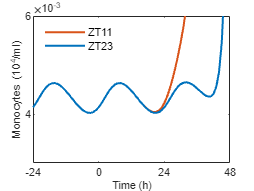


figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% plot(tspan, y1(:, 17), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan, y2(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan, y3(:, 17), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan, y4(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([476 548]);
xticks([476 500 524 548]);
% xlim([428 500]);
% xticks([428 452 476 500]);
xticklabels({'-24', '0', '24', '48'});
ylim([-3 2]);
ylim([0.003 0.006]);
yticks([0.004 0.006]);
% yticklabels({'0.60', '0.70'});
% yl = ylim;
% patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
% ylim(yl);
% xlabel('Time (h)');
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('Monocytes (10^4/ml)', 'Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'northwest');
% title('Phase of I_2 peak time');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

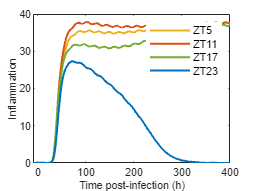

% turn over phase of mono and neu before infection
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
plot(tspan - t_IAV_5, infla1_phase, 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_11, infla2_phase, 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_17, infla3_phase, 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, infla4_phase, 'Color', color4(4, :), 'LineWidth', 1.5); 

xlim([-10 400]);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Inflammation','Fontsize',8, 'FontName', 'Arial');
legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

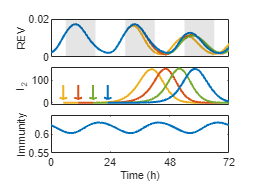

% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(3, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.7 0.7 0.2]);
plot(tspan(490:600), y1_phase(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan(490:600), y2_phase(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan(490:600), y3_phase(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4_phase(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([]);
yticks([0 0.02]);
% xticklabels({'0', '24', '48', '72'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(3, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.45 0.7 0.2]);
plot(tspan((t_IAV_5+1):end), y1_phase((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_11+1):end), y2_phase((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_17+1):end), y3_phase((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_23+1):end), y4_phase((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([]);
yticks([0 100]);
% yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
% ylim(yl);
% xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');

quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;

subplot(3, 1, 3); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.2]);
% plot(tspan, (y1(:, 17) + y1(:, 18) + y1(:, 23) + y1(:, 24) + y1(:, 25)), 'Color', color4(1, :), 'LineWidth', 1.5);
% plot(tspan, (y2(:, 17) + y2(:, 18) + y2(:, 23) + y2(:, 24) + y2(:, 25)), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan, (y3(:, 17) + y3(:, 18) + y3(:, 23) + y3(:, 24) + y3(:, 25)), 'Color', color4(3, :), 'LineWidth', 1.5);
% plot(tspan, (y4(:, 17) + y4(:, 18) + y4(:, 23) + y4(:, 24) + y4(:, 25)), 'Color', color4(4, :), 'LineWidth', 1.5); 
% plot(tspan, (y1(:, 17) + y1(:, 18)), 'Color', color4(1, :), 'LineWidth', 1.5);
% plot(tspan, (y2(:, 17) + y2(:, 18)), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan, (y3(:, 17) + y3(:, 18)), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan, (y4_phase(:, 17) + y4_phase(:, 18)), 'Color', color4(4, :), 'LineWidth', 1.5); 
% xlim([500 572]);
% xticks([500 524 548 572]);
xlim([428 500]);
xticks([428 452 476 500]);
xticklabels({'0', '24', '48', '72'});
ylim([0.55 0.65]);
yticks([0.55 0.6]);
% yticklabels({'0.60', '0.70'});
% yl = ylim;
% patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
% ylim(yl);
% xlabel('Time (h)');
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('Immunity', 'Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

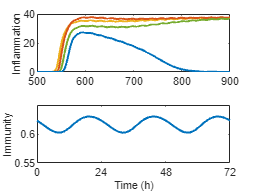


figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan, infla1_phase, 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan, infla2_phase, 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan, infla3_phase, 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan, infla4_phase, 'Color', color4(4, :), 'LineWidth', 1.5); 

xlim([500 900]);
ylabel('Inflammation','Fontsize',8, 'FontName', 'Arial');
% legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial');
% set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan, (y4_phase(:, 17) + y4_phase(:, 18)), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([428 500]);
xticks([428 452 476 500]);
xticklabels({'0', '24', '48', '72'});
ylim([0.55 0.65]);
yticks([0.55 0.6]);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('Immunity', 'Fontsize',8, 'FontName', 'Arial');
hold off;

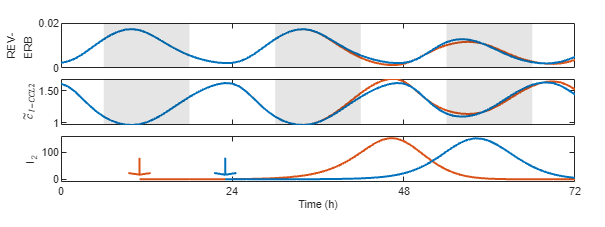

% PLot ERV-ERB phases of infection and peak time of I2
[~, peak_idx_I2_11] = max(y2(:, 15));
[~, peak_idx_I2_23] = max(y4(:, 15));


% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 16 6]);
subplot(3, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.7 0.85 0.2]);
% plot(tspan(490:600), y1(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan(490:600), y2(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan(490:600), y3(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
yticks([0 0.02]);
xticklabels({});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV-\newlineERB','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(3, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.45 0.85 0.2]);
% plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y1(:, 8)), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y2(:, 8)), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y3(:, 8)), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y4(:, 8)), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({});
yticks([1 1.5]);
yticklabels({'1', '1.50'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('$\tilde{c}_{I-CCL2}$', 'interpreter','latex', 'Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(3, 1, 3); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.2 0.85 0.2]);
% plot(tspan((t_IAV_5+1):end), y1((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_11+1):end), y2((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan((t_IAV_17+1):end), y3((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_23+1):end), y4((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
yticks([0 100]);
yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
ylim(yl);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');

% quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
% quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;

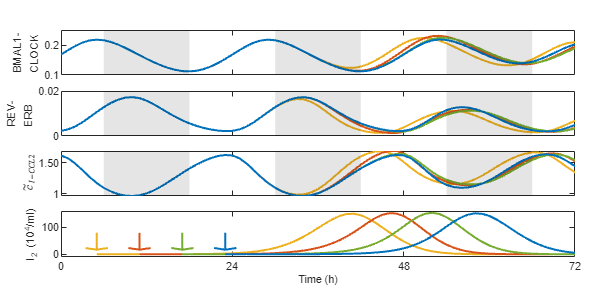

% PLot ERV-ERB phases of infection and peak time of I2
[~, peak_idx_I2_11] = max(y2(:, 15));
[~, peak_idx_I2_23] = max(y4(:, 15));


% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 16 8]);
subplot(4, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.75 0.85 0.15]);
plot(tspan(490:600), y1(490:600, 12), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan(490:600), y2(490:600, 12), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan(490:600), y3(490:600, 12), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4(490:600, 12), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
ylim([0.1 0.25]);
yticks([0.1 0.2]);
% yticklabels({'5', '10.0'});
xticklabels({});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('BMAL1-\newlineCLOCK','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(4, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.55 0.85 0.15]);
plot(tspan(490:600), y1(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan(490:600), y2(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan(490:600), y3(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
yticks([0 0.02]);
xticklabels({});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV-\newlineERB','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(4, 1, 3); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.35 0.85 0.15]);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y1(:, 8)), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y2(:, 8)), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y3(:, 8)), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y4(:, 8)), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({});
yticks([1 1.5]);
yticklabels({'1', '1.50'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('$\tilde{c}_{I-CCL2}$', 'interpreter','latex', 'Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(4, 1, 4); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.15 0.85 0.15]);
plot(tspan((t_IAV_5+1):end), y1((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_11+1):end), y2((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_17+1):end), y3((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_23+1):end), y4((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
yticks([0 100]);
yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
ylim(yl);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2 (10^4/ml)','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');

quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;

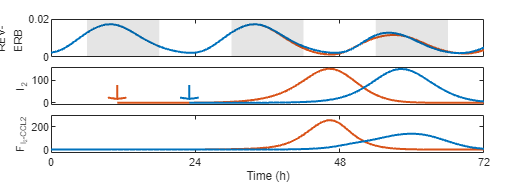

% PLot ERV-ERB phases of infection and peak time of I2
[~, peak_idx_I2_11] = max(y2(:, 15));
[~, peak_idx_I2_23] = max(y4(:, 15));


% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 13.46 5.05]);
subplot(3, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.7 0.85 0.2]);
% plot(tspan(490:600), y1(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan(490:600), y2(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan(490:600), y3(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
yticks([0 0.02]);
xticklabels({});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV-\newlineERB','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(3, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.45 0.85 0.2]);
% plot(tspan((t_IAV_5+1):end), y1((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_11+1):end), y2((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan((t_IAV_17+1):end), y3((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_23+1):end), y4((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([]);
% xticklabels({'0', '24', '48', '72'});
yticks([0 100]);
yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
ylim(yl);
% xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');
% 
% quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
% quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;

subplot(3, 1, 3); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.1 0.2 0.85 0.2]);
% plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y1(:, 8)) .* y1(:, 15), 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y2(:, 8)) .* y2(:, 15), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
% plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y3(:, 8)) .* y3(:, 15), 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y4(:, 8)) .* y4(:, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
ylim([-30 300]);
yticks([0 200]);
% yticklabels({'1', '1.50'});
% yl = ylim;
% patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
% ylim(yl);
xlabel('Time (h)');
ylabel('F_{I_2-CCL2}', 'Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;
% 
% subplot(4, 1, 4); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% set(gca, 'InnerPosition', [0.1 0.15 0.85 0.15]);
% plot(tspan, y1(:, 17), 'Color', color4(1, :), 'LineWidth', 1.5);
% plot(tspan, y2(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan, y3(:, 17), 'Color', color4(3, :), 'LineWidth', 1.5);
% plot(tspan, y4(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5); 
% xlim([500 572]);
% % ylim([0.003 0.006]);
% % yticks([0.004 0.006]);
% xticks([500 524 548 572]);
% xticklabels({'0', '24', '48', '72'});
% % yticks([0 100]);
% % yl = ylim;
% % plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% % plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
% % ylim(yl);
% xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
% ylabel('Monocytes','Fontsize',8, 'FontName', 'Arial');
% % title('Phase of infetion time');

hold off;

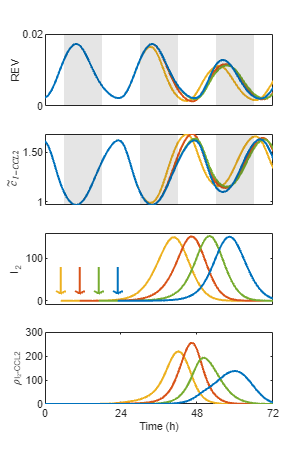

% PLot ERV-ERB phases of infection and peak time of I2
[~, peak_idx_I2_11] = max(y2(:, 15));
[~, peak_idx_I2_23] = max(y4(:, 15));


% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

% figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 12]);
subplot(4, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% set(gca, 'InnerPosition', [0.2 0.7 0.7 0.2]);
plot(tspan(490:600), y1(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan(490:600), y2(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan(490:600), y3(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([]);
yticks([0 0.02]);
% xticklabels({'0', '24', '48', '72'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(4, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% set(gca, 'InnerPosition', [0.2 0.45 0.7 0.2]);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y1(:, 8)), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y2(:, 8)), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y3(:, 8)), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y4(:, 8)), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([]);
% xticklabels({'0', '24', '48', '72'});
yticks([1 1.5]);
yticklabels({'1', '1.50'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('$\tilde{c}_{I-CCL2}$', 'interpreter','latex', 'Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(4, 1, 3); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% set(gca, 'InnerPosition', [0.2 0.2 0.7 0.2]);
plot(tspan((t_IAV_5+1):end), y1((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_11+1):end), y2((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_17+1):end), y3((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_23+1):end), y4((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([]);
yticks([0 100]);
yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
ylim(yl);
ylabel('I_2','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');

quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;

subplot(4, 1, 4); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% set(gca, 'InnerPosition', [0.2 0.2 0.7 0.2]);
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y1(:, 8)) .* y1(:, 15), 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y2(:, 8)) .* y2(:, 15), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y3(:, 8)) .* y3(:, 15), 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y4(:, 8)) .* y4(:, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('\rho_{I_2-CCL2}','Fontsize',8, 'FontName', 'Arial');

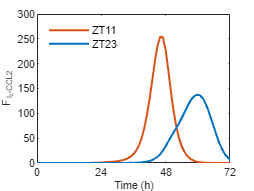


% c_I_CCL2 * I2
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% color2 = [254 129 125; 129 184 223] ./ 255;
% plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y1(:, 8)) .* y1(:, 15), 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y2(:, 8)) .* y2(:, 15), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
% plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y3(:, 8)) .* y3(:, 15), 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y4(:, 8)) .* y4(:, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('F_{I_2-CCL2}','Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Location', 'northwest', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

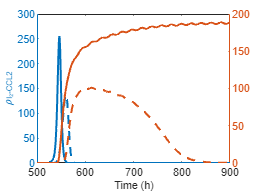

% c_I_CCL2 * I2 & c_m_CCL2 * Mono
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% color2 = [254 129 125; 129 184 223] ./ 255;


% plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y1(:, 8)) .* y1(:, 15), 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
% plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y2(:, 8)) .* y2(:, 15), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
% plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y3(:, 8)) .* y3(:, 15), 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
% plot(tspan, par_IAV(18) .* par_IAV(53) ./ (par_IAV(53) + y2(:, 10)) .* par_IAV(30) ./ (par_IAV(30) + y2(:, 20)) .* y2(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5);
yyaxis left;
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y2(:, 8)) .* y2(:, 15), 'LineWidth', 1.5);
% plot(tspan, par_IAV(18) .* par_IAV(53) ./ (par_IAV(53) + y4(:, 10)) .* par_IAV(30) ./ (par_IAV(30) + y4(:, 20)) .* y4(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(19) .* par_IAV(56) ./ (par_IAV(56) + y4(:, 8)) .* y4(:, 15), 'LineWidth', 1.5);
ylabel('\rho_{I_2-CCL2}','Fontsize',8, 'FontName', 'Arial');

yyaxis right;
plot(tspan, y2(:, 17), 'LineWidth', 1.5);
plot(tspan, y4(:, 17), 'LineWidth', 1.5);
xlim([500 900]);
% xticks([500 524 548 572]);
% xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
% legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Location', 'west', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

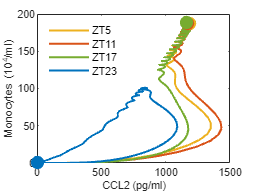

% Plot phase diagram of Mono-CCL2
figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
plot(y1(:, 21), y1(:, 17), 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(y2(:, 21), y2(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(y3(:, 21), y3(:, 17), 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(y4(:, 21), y4(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5);
sz = 100;
% c = [[223,57,42] ./ 255; 0 0 0];
scatter([y1(end, 21), y2(end, 21), y3(end, 21), y4(end, 21)], [y1(end, 17), y2(end, 17), y3(end, 17), y4(end, 17)], sz, color4, 'filled');
xlabel('CCL2 (pg/ml)', 'Fontsize',8, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)', 'Fontsize',8, 'FontName', 'Arial');
legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Location', 'northwest', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

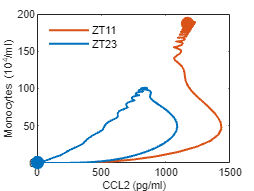


figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
plot(y2(:, 21), y2(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(y4(:, 21), y4(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5);
sz = 100;
% c = [[223,57,42] ./ 255; 0 0 0];
scatter([y2(end, 21), y4(end, 21)], [y2(end, 17), y4(end, 17)], sz, [color4(2, :); color4(4, :)], 'filled');
xlabel('CCL2 (pg/ml)', 'Fontsize',8, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)', 'Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Location', 'northwest', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

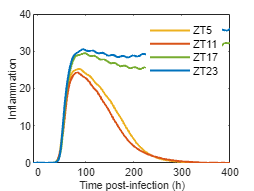

% change latent period(k1) and verify the mechanism
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
plot(tspan - t_IAV_5, infla1_k1, 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_11, infla2_k1, 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_17, infla3_k1, 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, infla4_k1, 'Color', color4(4, :), 'LineWidth', 1.5); 

xlim([-10 400]);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Inflammation','Fontsize',8, 'FontName', 'Arial');
legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

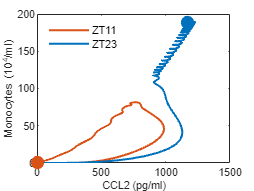


% Plot phase diagram of Mono-CCL2
figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
% plot(y1_k1(:, 21), y1_k1(:, 17), 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(y2_k1(:, 21), y2_k1(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
% plot(y3_k1(:, 21), y3_k1(:, 17), 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(y4_k1(:, 21), y4_k1(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5);
sz = 100;
% c = [[223,57,42] ./ 255; 0 0 0];
scatter([y2_k1(end, 21), y4_k1(end, 21)], [y2_k1(end, 17), y4_k1(end, 17)], sz, [color4(2, :); color4(4, :)], 'filled');
xlabel('CCL2 (pg/ml)', 'Fontsize',8, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)', 'Fontsize',8, 'FontName', 'Arial');
% legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Location', 'northwest', 'Fontsize',8, 'FontName', 'Arial');
legend('ZT11', 'ZT23', 'Box', 'off', 'Location', 'northwest', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

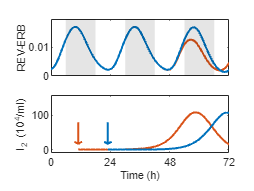


% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
% plot(tspan(490:600), y1_k1(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan(490:600), y2_k1(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan(490:600), y3_k1(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4_k1(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({});
yticks([0 0.01]);
% xticklabels({'0', '24', '48', '72'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV-ERB','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
% plot(tspan((t_IAV_5+1):end), y1_k1((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_11+1):end), y2_k1((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan((t_IAV_17+1):end), y3_k1((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_23+1):end), y4_k1((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
yticks([0 100]);
yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
ylim(yl);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2 (10^4/ml)','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');

% quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
% quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;

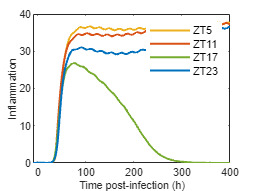

% change gamma and verify the mechanism
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
plot(tspan - t_IAV_5, infla1_gamma, 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_11, infla2_gamma, 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_17, infla3_gamma, 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, infla4_gamma, 'Color', color4(4, :), 'LineWidth', 1.5); 

xlim([-10 400]);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Inflammation','Fontsize',8, 'FontName', 'Arial');
legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

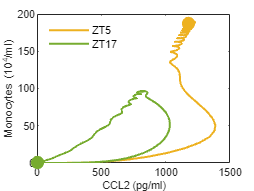


% Plot phase diagram of Mono-CCL2
figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
plot(y1_gamma(:, 21), y1_gamma(:, 17), 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
% plot(y2_gamma(:, 21), y2_gamma(:, 17), 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(y3_gamma(:, 21), y3_gamma(:, 17), 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
% plot(y4_gamma(:, 21), y4_gamma(:, 17), 'Color', color4(4, :), 'LineWidth', 1.5);
sz = 100;
% c = [[223,57,42] ./ 255; 0 0 0];
scatter([y1_gamma(end, 21), y3_gamma(end, 21)], [y1_gamma(end, 17), y3_gamma(end, 17)], sz, [color4(1, :); color4(3, :)], 'filled');
xlabel('CCL2 (pg/ml)', 'Fontsize',8, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)', 'Fontsize',8, 'FontName', 'Arial');
% legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Location', 'northwest', 'Fontsize',8, 'FontName', 'Arial');
legend('ZT5', 'ZT17', 'Box', 'off', 'Location', 'northwest', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

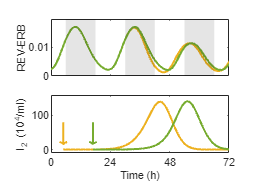


% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan(490:600), y1_gamma(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
% plot(tspan(490:600), y2_gamma(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan(490:600), y3_gamma(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
% plot(tspan(490:600), y4_gamma(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({});
yticks([0 0.01]);
% xticklabels({'0', '24', '48', '72'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV-ERB','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
plot(tspan((t_IAV_5+1):end), y1_gamma((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
% plot(tspan((t_IAV_11+1):end), y2_gamma((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_17+1):end), y3_gamma((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
% plot(tspan((t_IAV_23+1):end), y4_gamma((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
yticks([0 100]);
yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
ylim(yl);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2 (10^4/ml)','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');

quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
% quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
% quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;

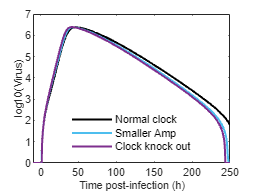

% clock disruption
figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_23, Safe_log10(y4(:, 16) - 100), 'Color', 'k', 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, Safe_log10(y4_sa(:, 16) - 100), 'Color', '#4DBEEE', 'LineWidth', 1.5); 
plot(tspan - t_IAV_23, Safe_log10(y4_ko(:, 16) - 100), 'Color', '#7E2F8E', 'LineWidth', 1.5); 

xlim([-10 250]);
ylim([0 7]);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('log10(Virus)', 'Fontsize',8, 'FontName', 'Arial');
% title('IAV', 'Fontsize',8, 'FontName', 'Arial');
legend('Normal clock', 'Smaller Amp', 'Clock knock out', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'south');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

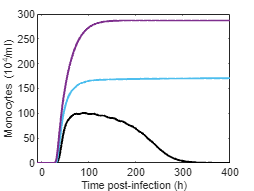


figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_23, y4(:, 17), 'Color', 'k', 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, y4_sa(:, 17), 'Color', '#4DBEEE', 'LineWidth', 1.5); 
plot(tspan - t_IAV_23, y4_ko(:, 17), 'Color', '#7E2F8E', 'LineWidth', 1.5); 

xlim([-10 400]);
xticks(0:100:400);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)', 'Fontsize',8, 'FontName', 'Arial');
% title('IAV', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

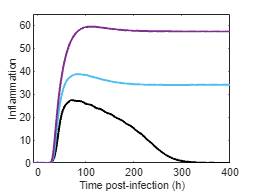

figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_23, infla4, 'Color', 'k', 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, infla4_sa, 'Color', '#4DBEEE', 'LineWidth', 1.5); 
plot(tspan - t_IAV_23, infla4_ko, 'Color', '#7E2F8E', 'LineWidth', 1.5); 

xlim([-10 400]);
ylim([0 65]);
xticks(0:100:400);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Inflammation', 'Fontsize',8, 'FontName', 'Arial');
% title('IAV', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

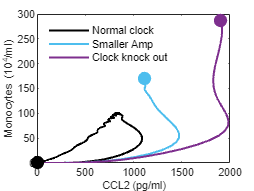


% color3 = [0, 0, 0; 66, 92, 170; 223,57,42] ./ 255;
color3 = [0 0 0; 0.3010 0.7450 0.9330; 0.4940 0.1840 0.5560];
% Plot phase diagram of Mono-CCL2
figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
plot(y4(:, 21), y4(:, 17), 'Color', 'k', 'LineWidth', 1.5); hold on;
plot(y4_sa(:, 21), y4_sa(:, 17), 'Color', '#4DBEEE', 'LineWidth', 1.5); hold on;
plot(y4_ko(:, 21), y4_ko(:, 17), 'Color', '#7E2F8E', 'LineWidth', 1.5);
sz = 100;
% c = [[223,57,42] ./ 255; 0 0 0];
scatter([y4(end, 21), y4_sa(end, 21), y4_ko(end, 21)], [y4(end, 17), y4_sa(end, 17), y4_ko(end, 17)], sz, color3, 'filled');
xlabel('CCL2 (pg/ml)', 'Fontsize',8, 'FontName', 'Arial'); ylabel('Monocytes (10^4/ml)', 'Fontsize',8, 'FontName', 'Arial');
legend('Normal clock', 'Smaller Amp', 'Clock knock out', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'northwest');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

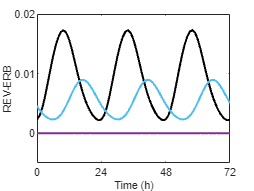

% clock disrpution - clock evolution
figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan, y4(:, 8), 'Color', 'k', 'LineWidth', 1.5); hold on;
plot(tspan, y4_sa(:, 8), 'Color', '#4DBEEE', 'LineWidth', 1.5); 
plot(tspan, zeros(2001, 1), 'Color', '#7E2F8E', 'LineWidth', 1.5); 

xlim([428 500]);
ylim([-0.005 0.02]);
xticks([428 452 476 500]);
xticklabels({'0', '24', '48', 72});
yticks([0 0.01 0.02]);
yticklabels({'0', '0.01', '0.02'});
xlabel('Time (h)', 'Fontsize',8, 'FontName', 'Arial'); ylabel('REV-ERB', 'Fontsize',8, 'FontName', 'Arial');
% title('IAV', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

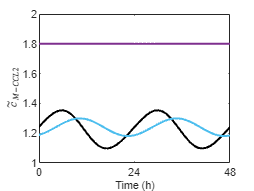

% clock disruption

figure; hold on; set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan, par_IAV(18) .* par_IAV(53) ./ (par_IAV(53) + y4(:, 12)), 'Color', 'k', 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(53) ./ (par_IAV(53) + y4_sa(:, 12)), 'Color', '#4DBEEE', 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(53) ./ (par_IAV(53) + zeros(2001, 1)), 'Color', '#7E2F8E', 'LineWidth', 1.5);
% plot(tspan, par_IAV(18) .* par_IAV(56) ./ (par_IAV(56) + y4_ko(:, 8)), 'Color', '#DF392A', 'LineWidth', 1.5);
xlim([200 248]);
ylim([1 2]);
xticks([200 224 248]);
xticklabels({'0', '24', '48'});
xlabel('Time (h)', 'Fontsize',8, 'FontName', 'Arial');
ylabel('$\tilde{c}_{M-CCL2}$', 'interpreter','latex', 'Fontsize',8, 'FontName', 'Arial');
% title('IAV', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

% red: 1.8, blue: [1.18 1.30], black: [1.10 1.35]

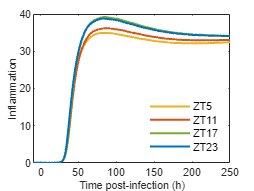

% different infection time for smaller amplitude
% Inflammation
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
plot(tspan - t_IAV_5, infla1_sa, 'Color', color4(1, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_11, infla2_sa, 'Color', color4(2, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_17, infla3_sa, 'Color', color4(3, :), 'LineWidth', 1.5); hold on;
plot(tspan - t_IAV_23, infla4_sa, 'Color', color4(4, :), 'LineWidth', 1.5); 

xlim([-10 250]);
xlabel('Time post-infection (h)','Fontsize',8, 'FontName', 'Arial'); ylabel('Inflammation','Fontsize',8, 'FontName', 'Arial');
legend('ZT5', 'ZT11', 'ZT17', 'ZT23', 'Box', 'off', 'Fontsize',8, 'FontName', 'Arial', 'Location', 'southeast');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

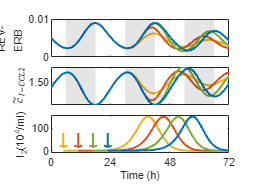


% dark regions
ymin = 0; ymax = 100;
v2 = [488 ymin; 494 ymin; 494 ymax; 488 ymax;
    506 ymin; 518 ymin; 518 ymax; 506 ymax;
    530 ymin; 542 ymin; 542 ymax; 530 ymax;
    554 ymin; 566 ymin; 566 ymax; 554 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12;
    13 14 15 16];

color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(3, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.7 0.7 0.2]);
plot(tspan(490:600), y1_sa(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan(490:600), y2_sa(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan(490:600), y3_sa(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4_sa(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({});
yticks([0 0.01]);
% xticklabels({'0', '24', '48', '72'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV-\newlineERB','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(3, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.45 0.7 0.2]);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y1_sa(:, 8)), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y2_sa(:, 8)), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y3_sa(:, 8)), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan, par_IAV(18) .* par_IAV(55) ./ (par_IAV(55) + y4_sa(:, 8)), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({});
% xticklabels({'0', '24', '48', '72'});
yticks([1 1.5]);
yticklabels({'1', '1.50'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('$\tilde{c}_{I-CCL2}$', 'interpreter','latex', 'Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(3, 1, 3); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.2]);
plot(tspan((t_IAV_5+1):end), y1_sa((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_11+1):end), y2_sa((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_17+1):end), y3_sa((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_23+1):end), y4_sa((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
yticks([0 100]);
yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
ylim(yl);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2(10^4/ml)','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');

quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;

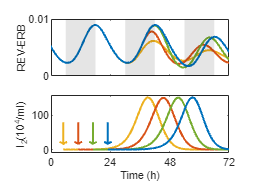


figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan(490:600), y1_sa(490:600, 8), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan(490:600), y2_sa(490:600, 8), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan(490:600), y3_sa(490:600, 8), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan(490:600), y4_sa(490:600, 8), 'Color', color4(4, :), 'LineWidth', 1.5); 
xlim([500 572]);
xticks([500 524 548 572]);
xticklabels({});
yticks([0 0.01]);
% xticklabels({'0', '24', '48', '72'});
yl = ylim;
patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylim(yl);
% xlabel('Time (h)');
ylabel('REV-ERB','Fontsize',8, 'FontName', 'Arial');
% title('Phase of I_2 peak time');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
plot(tspan((t_IAV_5+1):end), y1_sa((t_IAV_5+1):end, 15), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_11+1):end), y2_sa((t_IAV_11+1):end, 15), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_17+1):end), y3_sa((t_IAV_17+1):end, 15), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_IAV_23+1):end), y4_sa((t_IAV_23+1):end, 15), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([500 572]);
ylim([-10 160]);
xticks([500 524 548 572]);
xticklabels({'0', '24', '48', '72'});
yticks([0 100]);
yl = ylim;
% plot([511 511], [0 200], '--', 'Color', color2(1, :), 'LineWidth', 1.5);
% plot([523 523], [0 200], '--', 'Color', color2(2, :), 'LineWidth', 1.5);
ylim(yl);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2(10^4/ml)','Fontsize',8, 'FontName', 'Arial');
% title('Phase of infetion time');

quiver(t_IAV_5, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(1, :));
quiver(t_IAV_11, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(2, :));
quiver(t_IAV_17, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(3, :));
quiver(t_IAV_23, 80, 0, -70, 'LineWidth', 1.5, 'MaxHeadSize', 0.3, 'Color', color4(4, :));
hold off;